# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Autor(es): Isaac Marval y Diego Pena**

**Fecha: 17/10/2025**

El **objetivo** principal de esta práctica es familiarizarse con los operadores morfológicos.

close all
clear all

1) Lea la imagen en color 'autumn.tif' y muéstrela.

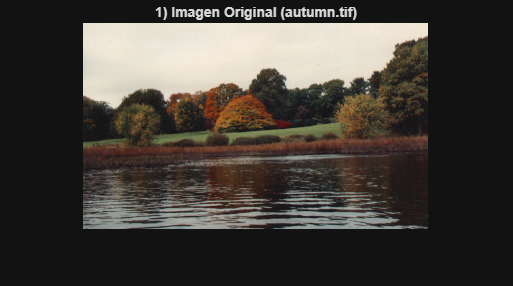


I_color = imread('imagenes/autumn.tif');
figure, imshow(I_color), title('1) Imagen Original (autumn.tif)');

2) Utilizando la función strel, cree un elemento estructurante con forma de disco de 5 píxeles de radio. 

radio = 5;
SE_disk = strel('disk', radio);
disp('Elemento Estructurante (SE):');

Elemento Estructurante (SE):


disp(SE_disk);

strel is a disk shaped structuring element with properties:

      Neighborhood: [9×9 logical]
    Dimensionality: 2



3) Erosione y dilate la imagen con dicho elemento estructurante y visualice las imágenes resultantes.

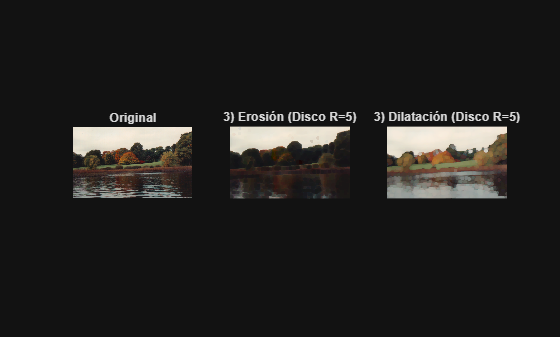

% 3) Erosione y dilate la imagen con dicho elemento estructurante y visualice las imágenes resultantes.
% Las operaciones morfológicas operan sobre cada canal de color (RGB) independientemente.
I_erosion = imerode(I_color, SE_disk);
I_dilatacion = imdilate(I_color, SE_disk);
figure;
subplot(1, 3, 1), imshow(I_color), title('Original');
subplot(1, 3, 2), imshow(I_erosion), title(['3) Erosión (Disco R=', num2str(radio), ')']);
subplot(1, 3, 3), imshow(I_dilatacion), title(['3) Dilatación (Disco R=', num2str(radio), ')']);

Además, se pide: 

- Ejecute el programa cargando la imagen en escala de grises `'rice.png' `y  la imagen binaria `'circles.png'`. Observe el comportamiento de los operadores morfológicos sobre los distintos tipos de imágenes.¿Qué diferencias ve?

- Elementos estructurantes. Observe el efecto de las operaciones morfológicas utilizadas en (3) con diferentes elementos estructurantes (ver ayuda: [https://es.mathworks.com/help/images/ref/strel.html?s_tid=doc_ta).](https://es.mathworks.com/help/images/ref/strel.html?s_tid=doc_ta).)

- Operadores morfológicos. Cargue la imagen en escala de grises `'rice.png' `y realice una operación de umbralizado con la función `imbinarize`, que por defecto utiliza el método de Otsu. Utilice las funciones `imclose` o `imopen` para eliminar los pequeños píxeles aislados que puedan estar en el fondo de la imagen. Tenga en cuenta que el tipo y tamaño del elemento estructurante debe ser ajustado.

- Repita la pregunta anterior pero utilizando la imagen original complementada (utilice la función `imcomplement`).

- Comente las diferencias en el efecto sobre los detalles en la imagen original y en la complementada.

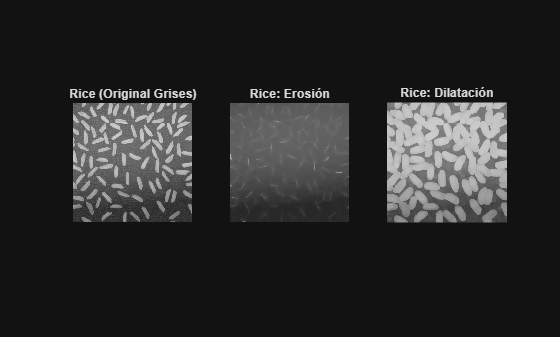

% 2. Efecto sobre Diferentes Tipos de Imágenes

% Cargando la imagen en escala de grises
I_rice = imread('rice.png');

% Aplicando las operaciones con el mismo SE (disco de radio 5)
rice_erosion = imerode(I_rice, SE_disk);
rice_dilatacion = imdilate(I_rice, SE_disk);

figure;
subplot(1, 3, 1), imshow(I_rice), title('Rice (Original Grises)');
subplot(1, 3, 2), imshow(rice_erosion), title('Rice: Erosión');
subplot(1, 3, 3), imshow(rice_dilatacion), title('Rice: Dilatación');

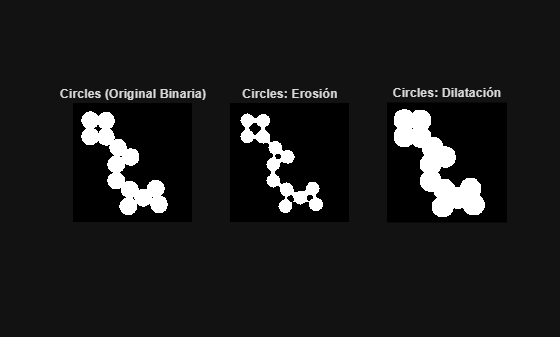


% Cargando la imagen binaria
I_circles = imread('circles.png');

% Aplicando las operaciones con el mismo SE (disco de radio 5)
circles_erosion = imerode(I_circles, SE_disk);
circles_dilatacion = imdilate(I_circles, SE_disk);

figure;
subplot(1, 3, 1), imshow(I_circles), title('Circles (Original Binaria)');
subplot(1, 3, 2), imshow(circles_erosion), title('Circles: Erosión');
subplot(1, 3, 3), imshow(circles_dilatacion), title('Circles: Dilatación');

% Cargando la imagen binaria
I_circles = imread('circles.png');

% Aplicando las operaciones con el mismo SE (disco de radio 5)
circles_erosion = imerode(I_circles, SE_disk);
circles_dilatacion = imdilate(I_circles, SE_disk);

figure;
subplot(1, 3, 1), imshow(I_circles), title('Circles (Original Binaria)');
subplot(1, 3, 2), imshow(circles_erosion), title('Circles: Erosión');
subplot(1, 3, 3), imshow(circles_dilatacion), title('Circles: Dilatación');

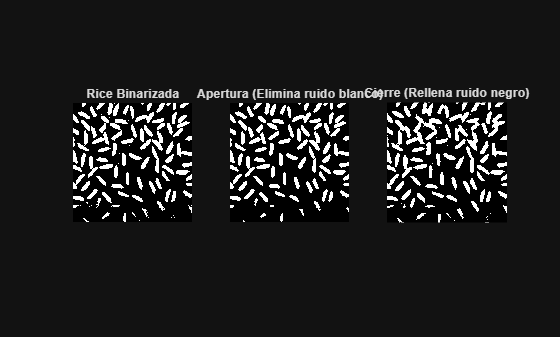

%% 3. Operaciones de Apertura y Cierre

I_rice = imread('rice.png');
% 1. Umbralizado (por defecto con Otsu)
I_binaria = imbinarize(I_rice);

% Elemento Estructurante: Disco pequeño.
SE_small = strel('disk', 2); 

% 2. Apertura (Erosión seguida de Dilatación): Elimina pequeños objetos BLANCOS aislados.
% Los pequeños puntos blancos en el fondo son eliminados.
I_apertura = imopen(I_binaria, SE_small);

% 3. Cierre (Dilatación seguida de Erosión): Rellena pequeños agujeros NEGROS y suaviza los bordes.

I_cierre = imclose(I_binaria, SE_small);

figure;
subplot(1, 3, 1), imshow(I_binaria), title('Rice Binarizada');
subplot(1, 3, 2), imshow(I_apertura), title('Apertura (Elimina ruido blanco)');
subplot(1, 3, 3), imshow(I_cierre), title('Cierre (Rellena ruido negro)');

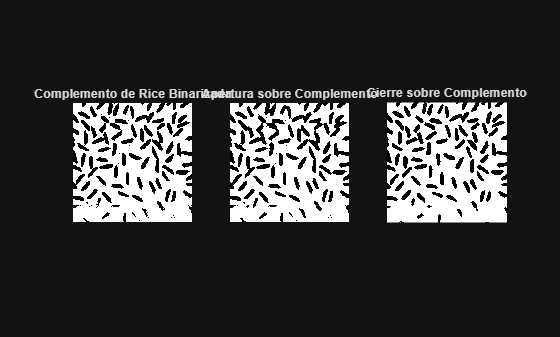

%% 3. Repetición con Imagen Complementada

% 1. Obtener la imagen complementada (figura negra sobre fondo blanco)
I_binaria_comp = imcomplement(I_binaria);

% 2. Apertura sobre el complemento:
% I_binaria_comp tiene ahora el ruido negro sobre fondo blanco.
% La apertura sobre este complemento (imopen(imcomplement)) elimina características BLANCAS PEQUEÑAS,
% es decir, ensancha las áreas negras (los granos de arroz).
I_apertura_comp = imopen(I_binaria_comp, SE_small);

% 3. Cierre sobre el complemento:
% El cierre sobre este complemento (imclose(imcomplement)) elimina características NEGRAS PEQUEÑAS,
% es decir, rellena los pequeños huecos dentro del fondo blanco.
I_cierre_comp = imclose(I_binaria_comp, SE_small);

figure;
subplot(1, 3, 1), imshow(I_binaria_comp), title('Complemento de Rice Binarizada');
subplot(1, 3, 2), imshow(I_apertura_comp), title('Apertura sobre Complemento');
subplot(1, 3, 3), imshow(I_cierre_comp), title('Cierre sobre Complemento');

%funciona mejor hacer la funcion de apertura en el fondo negro pero
%funciona mejor la funcion de cierre si el fondo es blanco.
% la funcion de apertura elimina mejor los detalles (ruido) mientras que la
% funcion de cierre se ven mejores los bordes de los objetos

Dada la imagen "HuellaOrig.jpg", que presenta ruido (tanto puntos negros dentro de la huella, como puntos blancos 

por fuera), se pide:

- Crear una imagen en la que se hayan eliminado los puntos blancos de ruido,

- A partir de dicha imagen, eliminar también los puntos negros dentro de la huella, para generar una imagen limpia. 

Para facilitar la comparación, las 3 imágenes deben mostrarse en la misma figura, con subplot, incluyendo el título correspondiente a cada una.

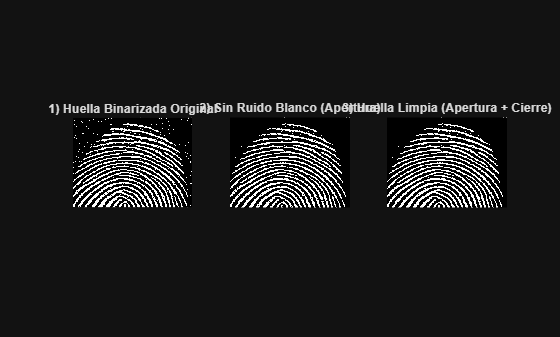

%% 4. Eliminación de Ruido en Huella 

clear all
close all

% 1. Cargar la imagen en color
original = imread('imagenes/HuellaOrig.jpg'); 

% 1.1. 🚨 CORRECCIÓN: Convertir la imagen RGB a escala de grises (2D).
I_huella_gray = rgb2gray(original); 

% 1.2. Binarizar: Ahora I_huella_bin será 2D (M x N) y de tipo lógico.
I_huella_bin = imbinarize(I_huella_gray); 

% Definir elemento estructurante: pequeño disco para eliminar ruido de puntos.
se_limpieza = strel('disk', 3);

% 2. Eliminar puntos BLANCOS de ruido (externos a la huella)
I_sin_ruido_blanco = imopen(I_huella_bin, se_limpieza); 

% 3. Eliminar puntos NEGROS dentro de la huella (ruido interno)
I_limpia = imclose(I_sin_ruido_blanco, se_limpieza); 

% 4. Visualización de los resultados
figure;
subplot(1, 3, 1)
imshow(I_huella_bin); % Esto ahora funciona
title('1) Huella Binarizada Original');

subplot(1, 3, 2)
imshow(I_sin_ruido_blanco);
title('2) Sin Ruido Blanco (Apertura)');

subplot(1, 3, 3)
imshow(I_limpia);
title('3) Huella Limpia (Apertura + Cierre)');

Dado el siguiente código:

% close all
% clear all

Step 1) Reading the Image

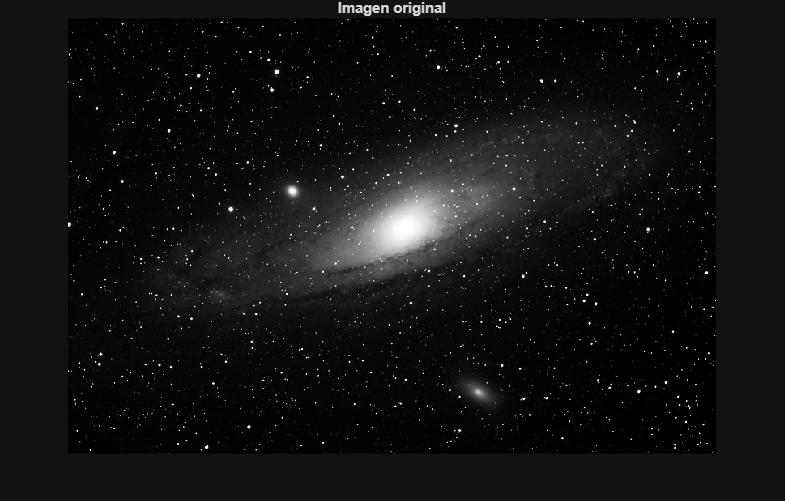

original = imread('imagenes/galaxy.png');
figure;
imshow(original);
title('Imagen original');

Step 2) Creating a structuring element.

se = strel('disk',6);

Step 3) Top or Bottom Hat.

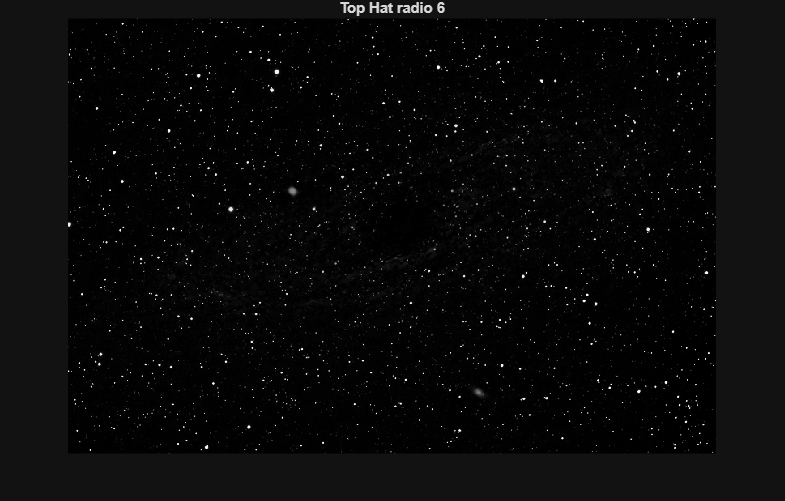

tophat = imtophat(original,se);
figure;
imshow(tophat);
title('Top Hat radio 6');

Se pide: 

- Supongamos que sólo nos interesan las pequeñas manchas en la imagen y queremos eliminar la galaxia. La operación (white) top-hat puede eliminar objetos brillantes más grandes y retener pequeñas manchas seleccionando correctamente el tamaño del elemento estructurante. Elija un elemento estructurante en forma de disco (2) y encuentre el radio que le permita mantener las estrellas pequeñas, un radio alrededor de 2 a 6 píxeles, y eliminar la galaxia, más de 50 píxeles. 

- Cuando el fondo es blanco y el primer plano es oscuro, debemos cambiar el enfoque. Obtenga la imagen complementada con la función `imcomplement` (1) y compruebe que La operación (white) top-hat no funciona correctamente. Explique por qué y obtenga una solución.

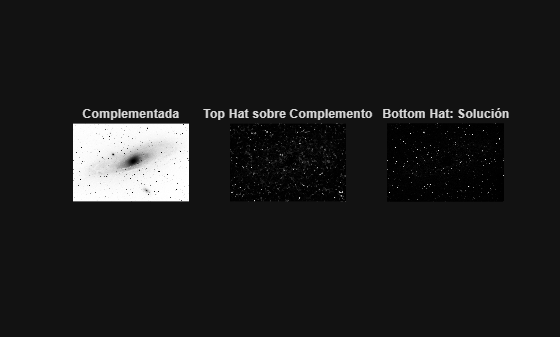



% 1) Obtener la imagen complementada (Fondo Blanco, Estrellas Oscuras)
I_comp = imcomplement(original);

figure;
subplot(1, 3, 1), imshow(I_comp), title('Complementada');

% 2) Comprobar que Top-Hat no funciona correctamente:
tophat_comp = imtophat(I_comp, se); % Usamos el SE de radio 4
subplot(1, 3, 2), imshow(tophat_comp), title('Top Hat sobre Complemento');

% 3) Solución: Usar Bottom-Hat.
% Bottom-Hat aísla objetos OSCUROS que son más pequeños que el SE.
% bottomhat(I) = imclose(I, SE) - I
bottomhat_comp = imbothat(I_comp, se);
subplot(1, 3, 3), imshow(bottomhat_comp), title('Bottom Hat: Solución');

% imtophat Extraer detalles Brillantes,
% con la imagen complemento no funciona
% imbothat Extraer detalles Oscuros,
% con la imagen original no funciona pero con la complemetaria si.


% Cuando el fondo es blanco y el objeto de interés (las estrellas) es oscuro, debemos usar 
% la operación Bottom-Hat (imbothat). Esta operación es la contraparte del Top-Hat y 
% extrae características oscuras que son más pequeñas que el elemento estructurante

